## Problem 17

global GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1
addpath('C:\Users\Luky\Desktop\DTU\Robotics\Assignment\alto_robot_matlab')

omega = 15;
zeta = 1;
T1 = 0;
T2 = -36.8734;
T3 = 60.3195;
T4 = -10.5752;
% T1 = 0;
% T2 = 0;
% T3 = 0;
% T4 = 0;
Jeff1=0.0198; % kgm^2
Jeff2=0.0242; % kgm^2
Jeff3=0.0027; % kgm^2
Jeff4=0.00038; % kgm^2
qr_1 = 0.35; % rad/s
qr_2 = 0.35; % rad/s
qr_3 = 0.35; % m
qr_4 = 0.35; % rad/s
kT = 0.17; % Nm/V
f = 0.000024; % Nm/(rad/s)
g = 9.81; % m/s^2;
GM = [0.1165, -0.58249, 0.77665, 0, 0, -0.34302; -0.00629, 0.03143, -0.0419, 0, 0, 1.75696; 0.06163, -0.30815, 0.41087, 0, 0, 1.51275; 0.00629, -0.03143, 0.0419, 0, 0, 2.95543; -0.09601, 0.48004, -0.64005, 0, 0, 0.2783; -0.00444, 0.02218, -0.02957, 0, 0, 1.72344; 0.06288, -0.31439, 0.41918, 0, 0, 1.84144; 0.00444, -0.02218, 0.02957, 0, 0, 2.98895; 0.08157, -0.40787, 0.54383, 0, 0, -0.23374; -0.00328, 0.01638, -0.02184, 0, 0, 1.69978; 0.06363, -0.31813, 0.42418, 0, 0, 2.17679; 0.00328, -0.01638, 0.02184, 0, 0, 3.01261; -0.07088, 0.3544, -0.47253, 0, 0, 0.20132; -0.00251, 0.01255, -0.01673, 0, 0, 1.68231; 0.06411, -0.32054, 0.42739, 0, 0, 2.51613; 0.00251, -0.01255, 0.01673, 0, 0, 3.03008];
a4 = 1.02; % m
d1 = 1.5; % m
B=f/kT;

Kd_1 = 9.3763;
Kd_2 = 10.1528;
Kd_3 = 6.35869;
Kd_4 = 5.94927;

Kp_1 = 202.6765;
Kp_2 = 208.5;
Kp_3 = 180.0441;
Kp_4 = 176.9735;

Ki_1 = 1323.5294;
Ki_2 = 1323.5294;
Ki_3 = 1323.5294;
Ki_4 = 1323.5294;

J1=Jeff1/kT;
J2=Jeff2/kT;
J3=Jeff3/kT;
J4=Jeff4/kT;

simulink = sim('problem17.slx',8);   % start simulation

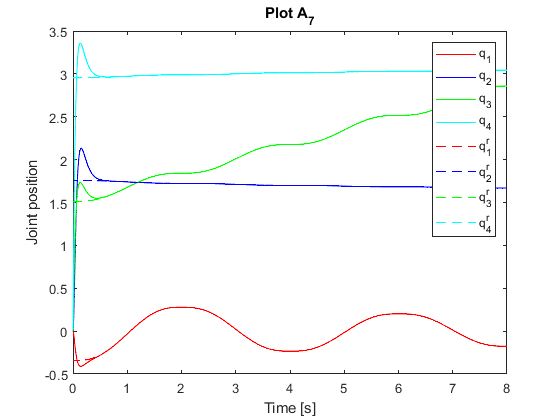

px = simulink.get('px');
py = simulink.get('py');
q1 = simulink.get('q1');
q2 = simulink.get('q2');
q3 = simulink.get('q3');
q4 = simulink.get('q4');
q1r = simulink.get('q1r');
q2r = simulink.get('q2r');
q3r = simulink.get('q3r');
q4r = simulink.get('q4r');
plot(q1.Time,q1.Data,'r'), hold on
plot(q2.Time,q2.Data,'b')
plot(q3.Time,q3.Data,'g')
plot(q4.Time,q4.Data,'c')
plot(q1r.Time,q1r.Data,'r--')
plot(q2r.Time,q2r.Data,'b--')
plot(q3r.Time,q3r.Data,'g--')
plot(q4r.Time,q4r.Data,'c--')
legend('q_1','q_2','q_3','q_4','q_1^r','q_2^r','q_3^r','q_4^r');
xlabel('Time [s]') 
ylabel('Joint position')
title('Plot A_7')
hold off

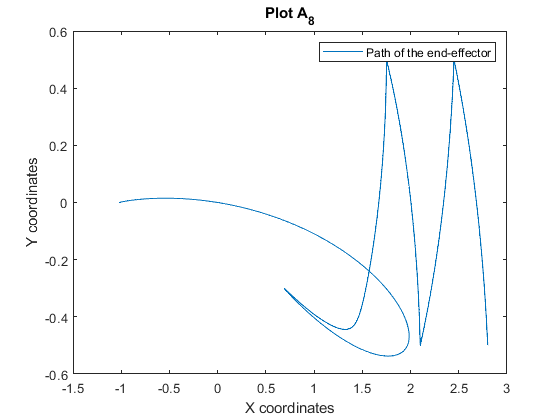


plot(px.Data,py.Data),hold on
legend('Path of the end-effector')
xlabel('X coordinates') 
ylabel('Y coordinates')
title('Plot A_8')
hold off


%animation could be seen in problem 20


## Problem 18

plot(px.Data,py.Data),hold on % using joint angles block
xlabel('X coordinates') 
ylabel('Y coordinates') % this is shady, but we use it for the graph below
GM = [0.06563, -0.32813, 0.4375, 0, 0, 1.4; 0.1875, -0.9375, 1.25, 0, 0, -0.5; 0.06563, -0.32813, 0.4375, 0, 0, 1.75; -0.1875, 0.9375, -1.25, 0, 0, 0.5; 0.06563, -0.32813, 0.4375, 0, 0, 2.1; 0.1875, -0.9375, 1.25, 0, 0, -0.5; 0.06563, -0.32813, 0.4375, 0, 0, 2.45; -0.1875, 0.9375, -1.25, 0, 0, 0.5];
simulink = sim('problem18.slx',8);   % start simulation

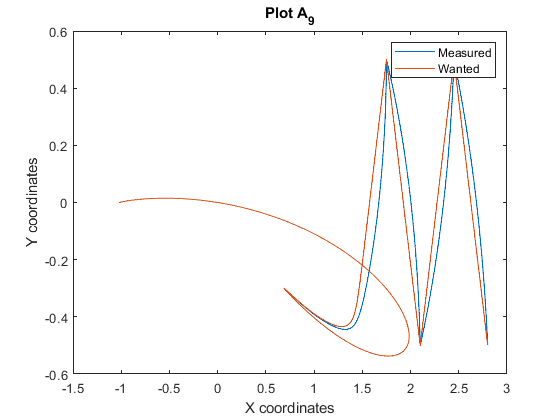

px2 = simulink.get('px2'); % reference
py2 = simulink.get('py2');
plot(px2.Data,py2.Data) % using cartesian + inverse block
title('Plot A_9')
legend('Measured','Wanted');